clear
close all
clc
load PETdata.mat
addpath("Functions\")

## Part A  - Forward Projection

# A1

thetas = 0:(size(G, 2)-1); % 0:179 
L = size(G, 1); 
R = L; C = L;

A = compute_forward_matrix(thetas, L, R, C);

# A2

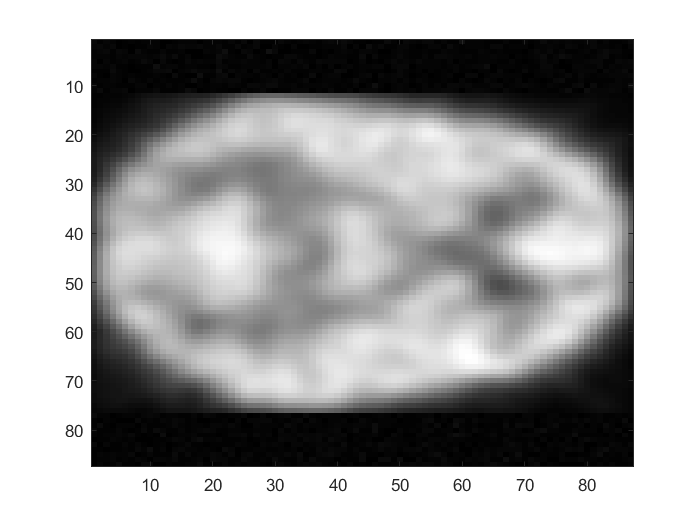

rec = NAIVE(A, G(:,:,10), [L, L, 1]);
imagesc(rec); colormap gray

## Part B - Iterative Reconstruction

# B1

Assume that $g_i$ is a Poisson distributed variable. Then the probability mass function is given as


$$P\left(g_i \right)=e^{-\bar{g_i } } \frac{\bar{g_i } }{g_i !}$$


The likelihood function, considering an iid sample of $g_i$ from a Poisson distribution,


$$L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)=P\left(g_{\;i} =g_{i1} \right)P\left(g_i =g_{i2} \right)\ldotp \ldotp \ldotp P\left(g_i =g_{\textrm{in}} \right)$$



$$L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)=\;$$

$$e^{-\bar{g_{\textrm{i1}} } } \frac{\bar{g_{\textrm{i1}} } }{g_{\textrm{i1}} !}e^{-\bar{g_{\textrm{i2}} } } \frac{\bar{g_{\textrm{i2}} } }{g_{\textrm{i2}} !}\ldotp \ldotp \ldotp e^{-\bar{g_{\textrm{in}} } } \frac{\bar{g_{\textrm{in}} } }{g_{\textrm{in}} !}$$



$$L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)\;=e^{-n\;\bar{g_i } } \frac{{\bar{g_i } }^{\sum_n g_i } }{\prod_n g_i !}$$


Then the log-likelihood is simply the logarithm of the above expression:


$$\ln \left(L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)\right)=-n\bar{g_i } +\left(\sum_n g_i \right)\ln \left(g_i \right)+\ln \left(\prod_n g_i !\right)$$


The derivative of this expression yields the Maximum Likelihood Estimator (MLE). We differentiate it with respect to $\bar{g_i }$.


$$\frac{d}{d\bar{g_i } }$$

$$\ln \left(L\left(\bar{g_i } |g_{\textrm{i1}} ,g_{\textrm{i2}} ,\ldotp \ldotp \ldotp ,g_{\textrm{in}} \right)\right)=-n+\frac{\left(\sum_n g_i \right)}{\hat{g_i } }$$
 

Setting to 0 and solving for $\hat{g_i }$ yields the MLE:


$$\hat{g_i } =\frac{\sum_n g_i }{n}$$


# B2

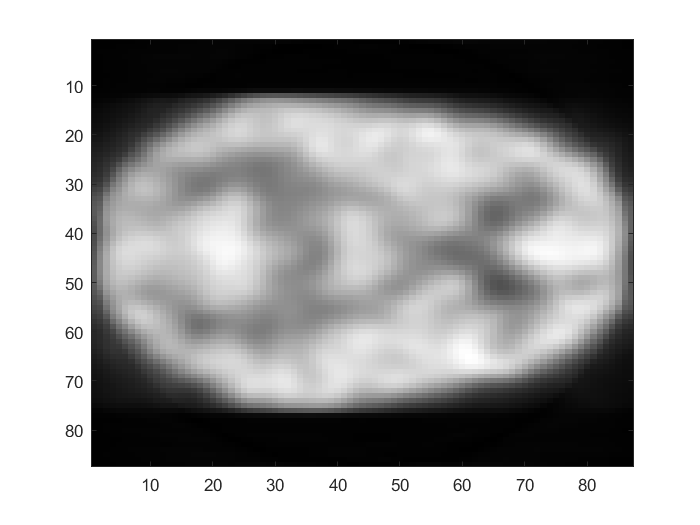

[rec_MLEM, error] = MLEM(A, G(:,:,10), [L, L, 1], 100);
imagesc(rec_MLEM);

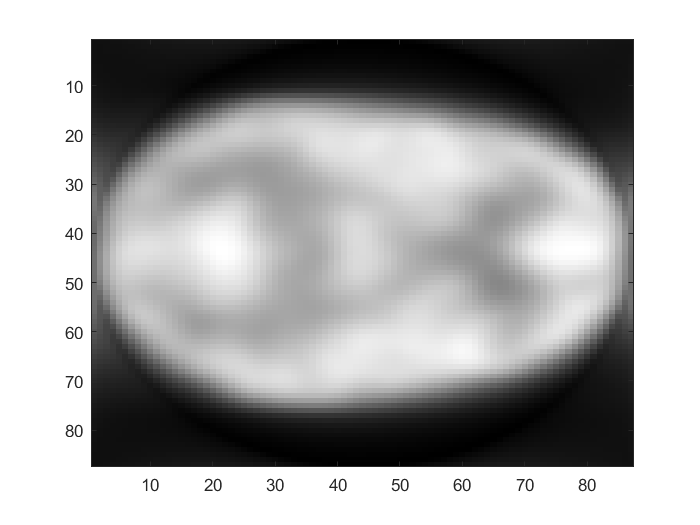

[rec_MLEM, error] = MLEM(A, G(:,:,10), [L, L, 1], 10);
imagesc(rec_MLEM);

## Part C - Iterative Reconstruction with Noisy Data

# C1

rec_noisy = NAIVE(A, G_noisy(:,:,10), [L,L,1]);

disp("G, without noise")

G, without noise


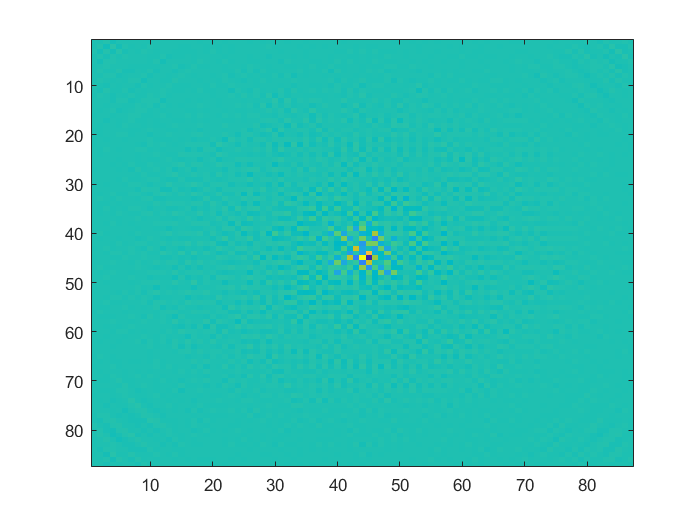

imagesc(rec); colormap gray

disp("G_noisy, noisy data")

G_noisy, noisy data


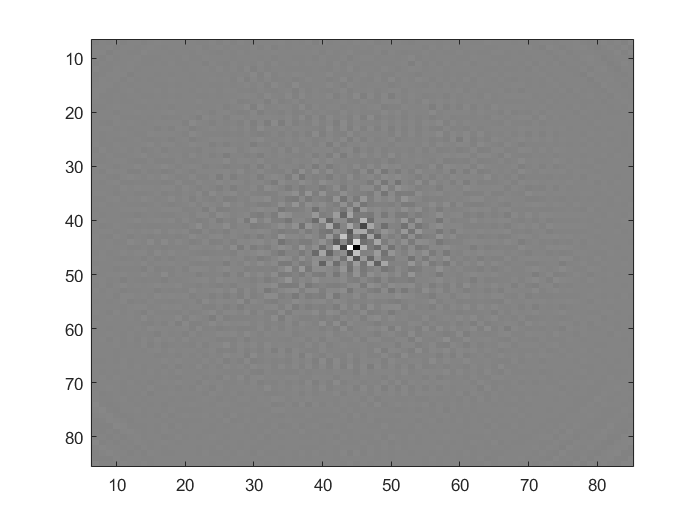

imagesc(rec_noisy); colormap gray

# C2

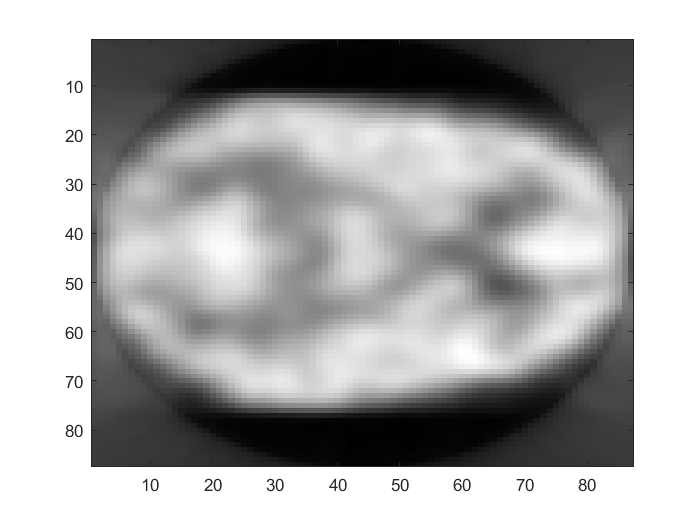

rec_FBP = FBP(G(:,:,10), thetas, [L, L, 1]);
imagesc(rec_FBP); colormap gray

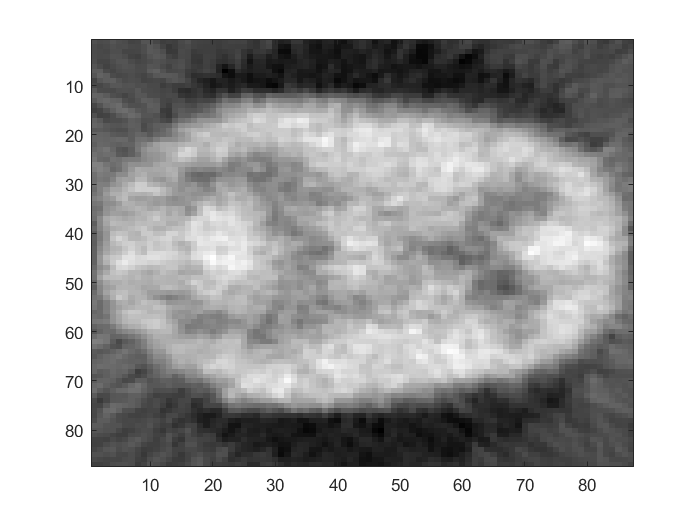

rec_FBP_noisy = FBP(G_noisy(:,:,10), thetas, [L, L, 1]);
imagesc(rec_FBP_noisy); colormap gray

# C3

num_iters = [10 20 50 75 100];
for n = num_iters
    disp(["num iters" n])
    [rec_MLEM_noisy, r_error_noisy] = MLEM(A, G_noisy(:,:,10), [L, L, 1], n);
    imagesc(rec_MLEM_noisy); colormap gray
end

    "num iters"    "10"



# C4

f_error = zeros(lenght(num_iters));
for iter = num_iters
    disp(["num iters" n])
    [rec_MLEM_noisy, r_error_noisy] = MLEM(A, G_noisy(:,:,10), [L, L, 1], n);
    f_error(iter) = sumsqr(rec_MLEM_noisy - rec_MLEM);
end
plot(f_error)
title("sumo of square error of noisy MLEM rec. and MLEM rec.")